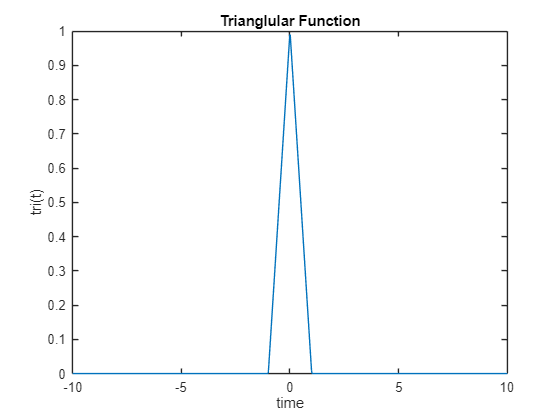

rect = @(t) double(abs(t) <= 0.5);
tri = @(t, T) (abs(t) < T) .* (1 - abs(t) / T) + (abs(t) >= T) .* 0;


function result=general_fourier_transform (f)
    result= @(omega) integral(@(t) f(t) .* exp(-1j * omega * t), -inf,inf, 'ArrayValued', true);
end

function tri=triangular_function(t,T,Shift)
    t_prim= t-Shift;
    tri=(1-abs(t_prim)/T) .* (abs(t_prim)<T) +(abs(t_prim)>= T).* 0;
end

function F=triangular_fourier_transform(T ,w_vals)
    tri = @(t, T) (abs(t) < T) .* (1 - abs(t) / T) + (abs(t) >= T) .* 0;
    Transform =@(w) integral(@(t)  tri(t,T).* exp(-1j * w * t), -inf,inf, 'ArrayValued', true);
    F=arrayfun(Transform,w_vals);
end

omega=linspace(-20,20,1000);
time=linspace(-10,10,1000);

%triangular function
plot(time,triangular_function(time,1,0));
title('Trianglular Function');
xlabel('time');
ylabel('tri(t)');

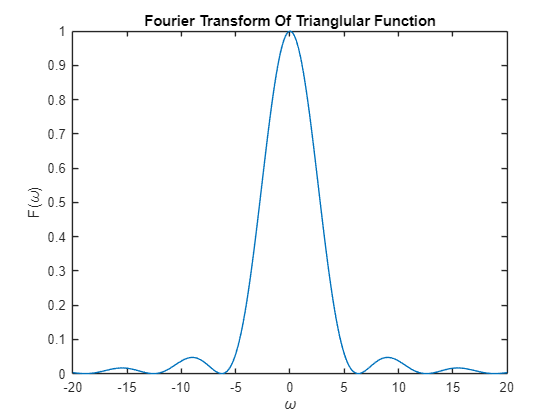


%fourier transform of triangular function
plot(omega,abs(triangular_fourier_transform(1,omega)));
title('Fourier Transform Of Trianglular Function');
xlabel('\omega');
ylabel('F(\omega)');


function F=approximate_fourier_transform(f,t,w_vals)

    f_array=arrayfun(f,t);
    idx=find(f_array);

    first_index=idx(1);
    last_index=idx(end);
    F =zeros(size(f_array));
    for m= first_index:(last_index)
        F=F + f_array(m) * triangular_fourier_transform(1,w_vals) * exp(-1j * m * w_vals(m));
        
    end
  
end
f1=@(t) rect(t/5)*(1-cos(2*pi*t/5));
f2=@(t) tri(t,1)+tri(t-2,1)+tri(t-4,1)+tri(t-6,1);

subplot(2,2,1);
plot(omega,(arrayfun(general_fourier_transform(f1),omega)));

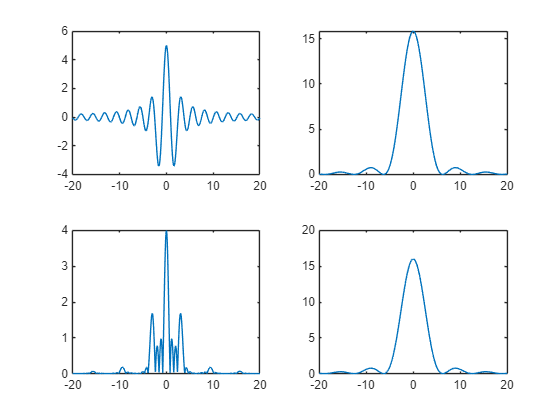


subplot(2,2,2);
plot(omega,abs(approximate_fourier_transform(f1,time,omega)));
subplot(2,2,3);
plot(omega,abs(arrayfun(general_fourier_transform(f2),omega)));

subplot(2,2,4);
plot(omega,abs(approximate_fourier_transform(f2,time,omega)));